# Bifurcación Lotka Volterra  sin Competencia.

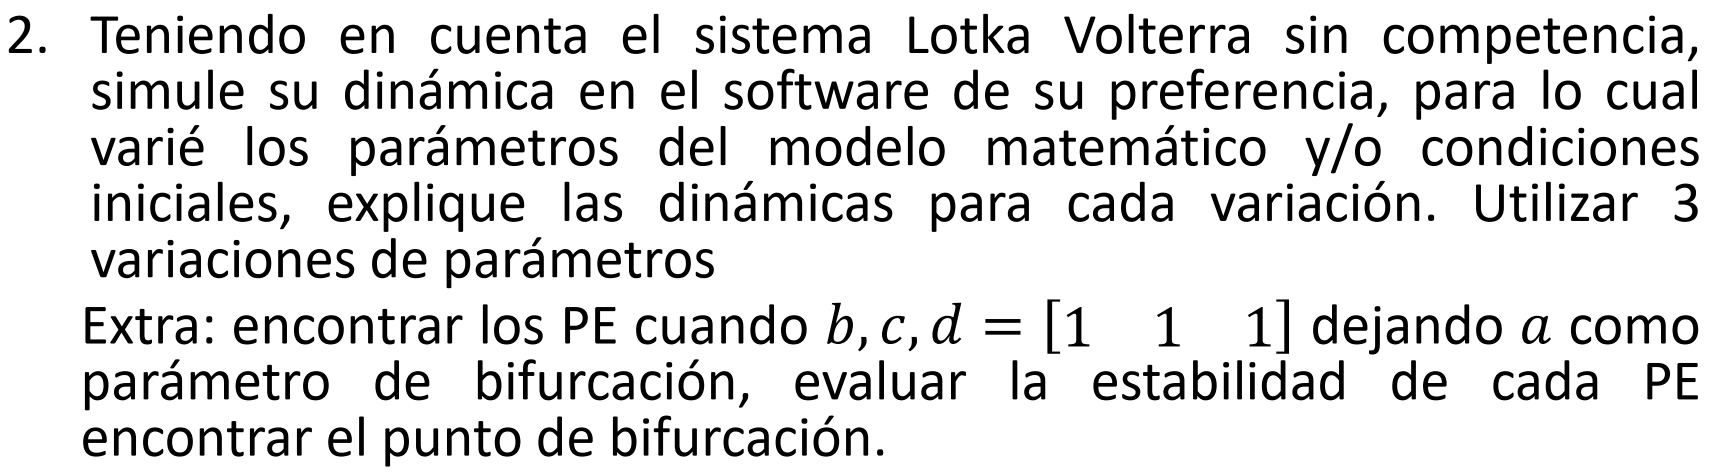

Modelo comportamiento población de dos especies:

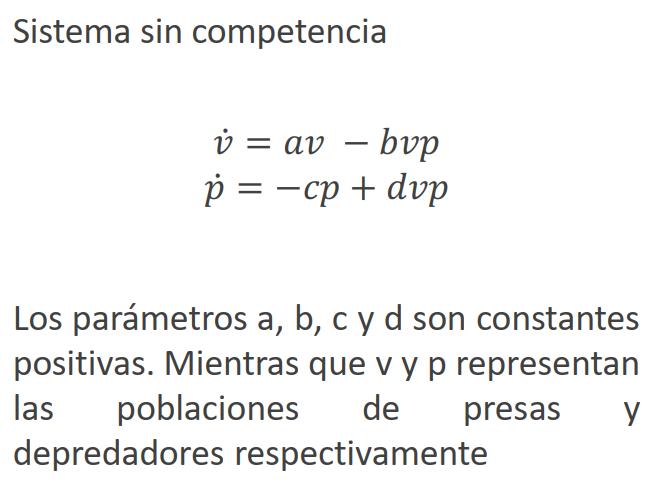

Parámetros:  

- **v**: presas. 

- **p**: depredador. 

- **a**: nacimientos presas. 

- **b**: mortalidad de presas (factibilidad de encontrarse con depredador).

- **vp**: interacción de ambas especies. 

- **c**: muerte natural depredador. 

- **d**: crecimiento de depredadores.

- **av**: cambio del numero de presas esta determinado por su propio crecimiento

- **bvp**: taza de encuentro con la especie depredadora.

- **dvp**: crecimiento de depredadores por la caza de presas 

- **-cp**: muerte causas naturales de los depredadores.

Se asume en este modelo que las presas tienen **suministros** de comida **ilimitados** por un tiempo definido con taza de reproduccion exponencial almenos que exista un depredador.

La poblacion depende del crecimiento de las presas.

syms a v c p b d

vps = a*v-b*v*p;
pps = -c*p+d*v*p;
Fs = [vps;pps]

$$Fs = \left(\begin{array}{c} a\,v-b\,p\,v\\ d\,p\,v-c\,p \end{array}\right)$$



As = jacobian(Fs,[v p]);
a_num=1 %Parámetro bifurcación. Asignado.

a_num = 1

As = subs(As,a,a_num) %parámetro bifurcación. asignamos a=1.

$$As = \left(\begin{array}{cc} 1-b\,p & -b\,v\\ d\,p & d\,v-c \end{array}\right)$$

val_prs = eig(As) %?

$$val\_prs = \begin{array}{l} \left(\begin{array}{c} \frac{d\,v}{2}-\frac{b\,p}{2}-\frac{c}{2}-\sigma_{1}+\frac{1}{2}\\ \frac{d\,v}{2}-\frac{b\,p}{2}-\frac{c}{2}+\sigma_{1}+\frac{1}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{b^{2}\,p^{2}-2\,b\,c\,p-2\,b\,d\,p\,v-2\,b\,p+c^{2}-2\,c\,d\,v+2\,c+d^{2}\,v^{2}-2\,d\,v+1}}{2} \end{array}$$


tspan = [0 50]; % Tiempo de simulación
x0presa = 2   % Condiciones iniciales [presa, depredador] +++++++++++++++++++++++++++

x0presa = 2

x0depreda = 0.2

x0depreda = 0.2000

% Parámetros
%bcd1 = [1 1 1]; %positivos.
%bcd2 = [1 2 3]; %positivos.
%bcd3 = [2 3 4]; %positivos.
b1=1,c1=1,d1=1

b1 = 1

c1 = 1

d1 = 1

b2=0.5,c2=0.2,d2=1

b2 = 0.5000

c2 = 0.2000

d2 = 1

b3=4,c3=3,d3=0.5

b3 = 4

c3 = 3

d3 = 0.5000

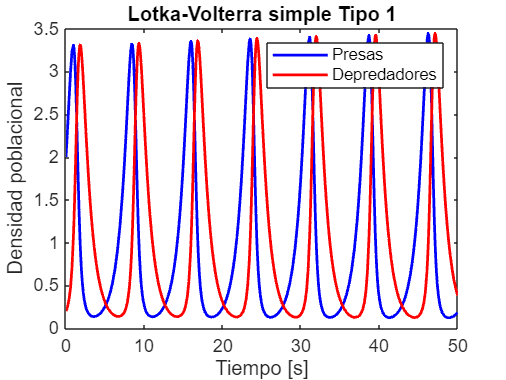



%a es punto bifurcación

% Solución ED's
[t1, y1] = simular(a_num, b1, d1, c1, x0presa, x0depreda, tspan);
[t2, y2] = simular(a_num, b2, d2, c2, x0presa, x0depreda, tspan);
[t3, y3] = simular(a_num, b3, d3, c3, x0presa, x0depreda, tspan);

%{Gráficas
%subplot(1,3,1)
plot(t1,y1(:,1),'b',t1,y1(:,2),'r','LineWidth',1.5)
xlabel('Tiempo [s]'); ylabel('Densidad poblacional');

legend('Presas','Depredadores'); title("Lotka-Volterra simple Tipo 1");

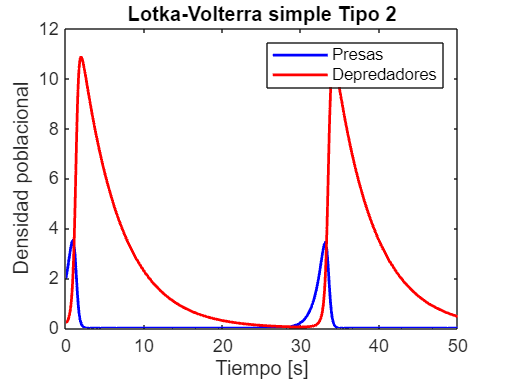


%subplot(1,3,2)
plot(t2,y2(:,1),'b',t2,y2(:,2),'r','LineWidth',1.5)
xlabel('Tiempo [s]'); ylabel('Densidad poblacional');
%ylim([0 12e21])
legend('Presas','Depredadores'); title("Lotka-Volterra simple Tipo 2");  

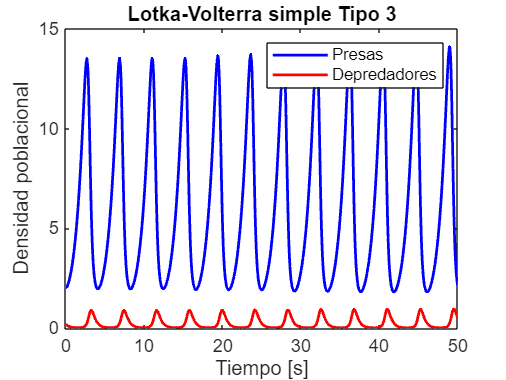


%subplot(1,3,3)
plot(t3,y3(:,1),'b',t3,y3(:,2),'r','LineWidth',1.5)
xlabel('Tiempo [s]'); ylabel('Densidad poblacional');
%ylim([0 12e21])
legend('Presas','Depredadores'); title("Lotka-Volterra simple Tipo 3");  

%{
function [t, y] = simular(alpha, beta, delta, gamma, x0, y0, tspan)
    dydt = @(t, y) [alpha*y(1) - beta*y(1)*y(2); delta*y(1)*y(2) - gamma*y(2)];
    [t, y] = ode45(dydt, tspan, [x0, y0]);
end
%}
%Parámetros: alpha, beta, delta, gamma, x0, y0, tspan -->
function [t, y] = simular(a, b, d, c, x0presa, x0depreda, tspan)
    dydt = @(t, y) [a*y(1) - b*y(1)*y(2); d*y(1)*y(2) - c*y(2)];
    [t, y] = ode45(dydt, tspan, [x0presa, x0depreda]);
end

# EXTRA.

Extra: encontrar los PE cuando 𝑏, 𝑐, 𝑑 = [1 1 1] dejando 𝑎 como parámetro de bifurcación, evaluar la estabilidad de cada PE encontrar el punto de bifurcación.  

**PUNTO EQUILIBRIO: 0,0.**

**ESTABILIDAD: Estable si a<0, insetable si a>0. Medio estable si a=0.**

**PUNTO BIFURCACION: a.**